## Adnan Akortal & Yimin Pan

# Template of Manipulator Short project: Skull tumor surgery

**List of to do:**

The Robotic environment must contain:

1.- Operating table. It can be raised, lowered, and tilted in any direction, and an  auxiliary table for the tools. Use 'patch' or 'fill3' functions to model it.

*We create 2 tables, a smaller one for the tools and another for the operation where the pacient will be laid. *

*Here we can switch the boolean 'applyTransform' to add the rotation and translation asked in exercise 12.*

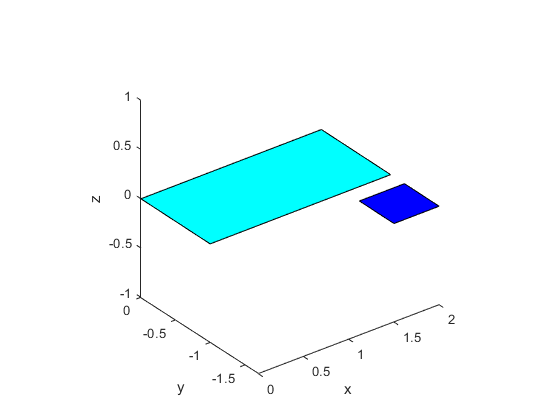

clear;
clf;
clc;
close all;

tableTransform = eye(4);
rotation = eye(4);
translation = eye(4);

% Create the operations table (2 x 1 meters)
matrix = [0 0 0;
          0 2 0;
          1 2 0;
          1 0 0];

operationTable = fill3(matrix(:,1),matrix(:,2),matrix(:,3),'c');
operationTable.Vertices = Transform(operationTable.Vertices, trotz(-pi/2));
hold on;

applyTransform = false;
if applyTransform
    % Rotamos la tabla 10 grados en X y 30 grados en Z
    rotation = trotz(pi/6)*troty(-pi/18);
    operationTableAux = Transform(operationTable.Vertices, rotation);
    translation = transl([10,10,0.8]-operationTableAux(2,:));
    tableTransform = translation*rotation;
end

operationTable.Vertices = Transform(operationTable.Vertices, tableTransform);
% Create the auxiliary table (0.5 x 0.5 meters)
matrix = [1.2 1.5 0;
          1.2   2 0;
          1.7   2 0;
          1.7 1.5 0];
toolTable = fill3(matrix(:,1),matrix(:,2),matrix(:,3),'b');
toolTable.Vertices = Transform(toolTable.Vertices, trotz(-pi/2));
toolTable.Vertices = Transform(toolTable.Vertices, tableTransform);
zlabel('z');ylabel('y');xlabel('x');
axis equal

2.- A 3D model of a human body on the operating table. Use the Workspace given, or other you might find.

*We load the human's body model and resize it from 10m to 1.8m.*

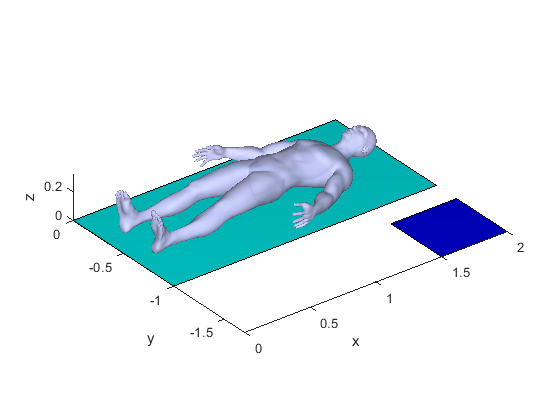

%% put your code Here
HumanBody = load("Model\F_V_Human_Body.mat");

humanYmax = max(HumanBody.V(:, 2));
humanYmin = min(HumanBody.V(:, 2));
HumanBody.V = HumanBody.V / ((humanYmax - humanYmin) / 1.8);
humanXmin = min(HumanBody.V(:, 1));
humanYmax = max(HumanBody.V(:, 2));
humanZmin = min(HumanBody.V(:, 3));
Upperleft = [humanXmin, humanYmax, humanZmin];

HumanBody.V = Transform(HumanBody.V, trotz(-pi/2)*transl([0,1.9,0]-Upperleft));
HumanBody.V = Transform(HumanBody.V, tableTransform);

patch('Faces', HumanBody.F, 'Vertices', HumanBody.V,...
      'FaceColor',[0.8 0.8 1.0],...
      'EdgeColor','none',...
      'FaceLighting',    'gouraud',     ...
      'AmbientStrength', 0.8,'FaceAlpha', 0.8);
camlight('headlight');
material('dull');
axis equal

3.- A human skull model, embedded in the head of the human. Place the fiducials.

*1) We load the skull model and resize it to the humans dimention, then we add it to the plot.*

*2) We create three spheres to represent the fiducials of the dicom images, their coordinates are taken manually from the images.*

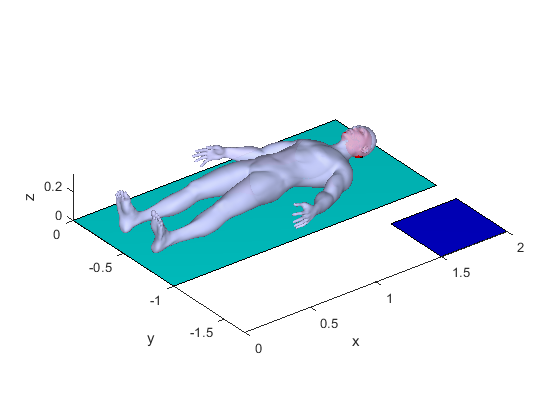

% put your code Here
Skull = load("Model\F_V_N_Skull.mat");

SkullYmax = max(Skull.Ve(:, 2));
SkullYmin = min(Skull.Ve(:, 2));
Skull.Ve = Skull.Ve / ((SkullYmax - SkullYmin) / 0.2);

Skull.Ve = Transform(Skull.Ve, transl([1.68, -0.505, 0.15])*trotz(-pi/2)*trotx(-pi/2));
Skull.Ve = Transform(Skull.Ve, tableTransform);

SkullPatch = patch('Faces', Skull.Fa, 'Vertices', Skull.Ve,...
      'FaceColor', 'red' ,...
      'EdgeColor','none');
material('dull');
axis equal

% ------------ Fiducials ----------------
scale = 0.1 / 122; % Tamaño que queremos en eje Y / Tamaño real (185-73)

fiducials = [213 73 32*2; 213 185 65*2; 213 122 94*2];
fiducials = fiducials*scale;
transformacionImg = tableTransform*transl(1.72, -0.615, 0.25)*troty(pi/2);
%transformacionImg = troty(pi/2) * transl(-0.25, -0.615, 1.72)*tableTransform;
fiducials = Transform(fiducials, transformacionImg);

scaleSphere = 1/150;

[X1, Y1, Z1] = sphere;
X1 = X1*scaleSphere+fiducials(1,1); Y1 = Y1*scaleSphere+fiducials(1,2); 
Z1 = Z1*scaleSphere+fiducials(1,3);
surf(X1,Y1,Z1);

[X2, Y2, Z2] = sphere;
X2 = X2*scaleSphere+fiducials(2,1); Y2 = Y2*scaleSphere+fiducials(2,2); 
Z2 = Z2*scaleSphere+fiducials(2,3);
surf(X2,Y2,Z2);

[X3, Y3, Z3] = sphere;
X3 = X3*scaleSphere+fiducials(3,1); Y3 = Y3*scaleSphere+fiducials(3,2);
Z3 = Z3*scaleSphere+fiducials(3,3);
surf(X3,Y3,Z3);

axis equal
axis tight

#### Reference frame of the fiducial (by creating a triangle with these three points)

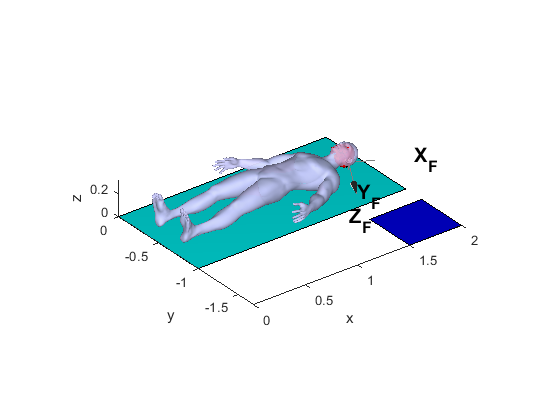

length = 0.5;
width = 1.5;
P = fiducials';
AB=(P(:,1)-P(:,2))/norm(P(:,1)-P(:,2)); 
CB=(P(:,3)-P(:,2))/norm(P(:,2)-P(:,3)); 
A = cross(CB, AB)/norm(cross(CB, AB)); % Approach vector 
RF = oa2r(AB, A); 
center = [mean(P(1,:)), mean(P(2,:)), mean(P(3,:))]'; % Center of the triangle
TF = [RF, center; 0 0 0 1]; 
trplot(TF, ... 
        'frame', 'F', ... 
        'color', 'black',...
        'arrow',...
        'length', length,...	
        'text_opts', {'FontSize', 15, 'FontWeight', 'bold'},...
        'width', width);

4.- Use the Dicom images to get the points of the outer perimeter of the tumor relative to some reference frame located in the human skull.

*The tumor (points) are gotten using computer vision techniques (morphological operations) over the dicom images. We iterate over each image and get the tumor points for that layer. Finally we mix all the layers to get a 3d model for the tumor.*

*Later we scale its size to match the humans skull (with the same scale as the fiducials), and move it to the correct spot.*

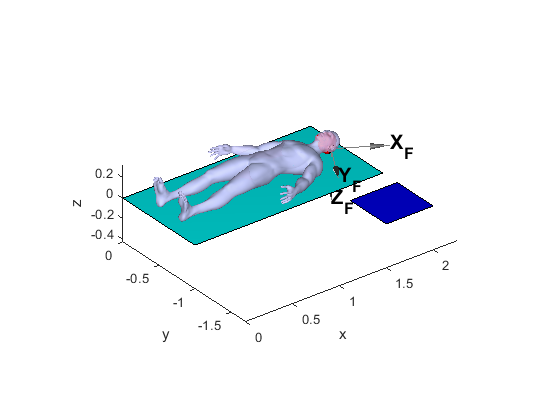

% put your code Here
points = double.empty(0,3);
for i = 65:89
    path = cat(2,['DICOM\IMG00'], num2str(i),['.dcm']);
    I = dicomread(path);
    BW = imbinarize(mat2gray(I),'adaptive');
    R = regionprops(BW, 'PixelList','PixelIdxList');
    for j = 1:size(R)
        if ~ismember([129,95],R(j).PixelList,'rows')
            BW(R(j).PixelIdxList) = 0;
        end
    end
    se = strel('disk', 3);
    filtered = imopen(BW, se);
    filtered = bwareafilt(filtered,1);
    filtered = imfill(filtered,'holes');
    se = strel('disk', 5);
    filtered = imclose(filtered, se);
    perimetre = bwperim(filtered);
    R = regionprops(filtered,'PixelList');
    for j = 1:size(R.PixelList)
        points = [points; [R.PixelList(j,2) R.PixelList(j,1) i*2]];
    end
end

points = points*scale;
T_P_Img = mean(points);
p = Transform(points, transformacionImg);

tumor = patch('XData', p(:,1), 'YData', p(:,2), 'ZData', p(:,3),'FaceColor', 'black' ,...
      'EdgeColor','none');

axis equal
axis tight

5.- Display all necessary Reference Frames

*Print all the reference frames*

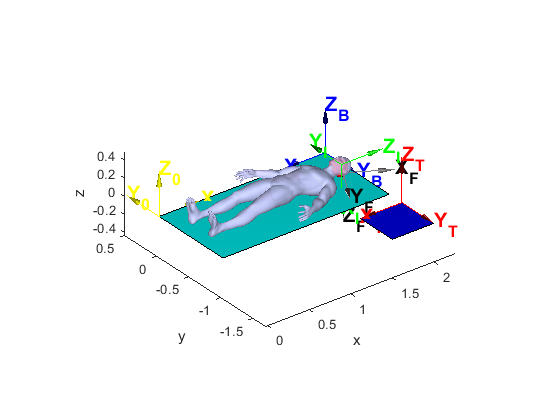

%% put your code Here

% origin (0,0,0)
Z = transl(0,0,0) * tableTransform; 
trplot(Z, ... 
        'frame', '0', ... 
        'color', 'y',...
        'arrow',...
        'length', length,...	
        'text_opts', {'FontSize', 15, 'FontWeight', 'bold'},...
        'width', width);
    
% Image
I = transformacionImg;
trplot(I, ... 
        'frame', 'I', ... 
        'color', 'g',...
        'arrow',...
        'length', length,...	
        'text_opts', {'FontSize', 15, 'FontWeight', 'bold'},...
        'width', width);
    
% Body Table 
BT = transl(operationTable.Vertices(2,:))*rotation*trotz(-pi);
trplot(BT, ... 
        'frame', 'B', ... 
        'color', 'b',...
        'arrow',...
        'length', length,...	
        'text_opts', {'FontSize', 15, 'FontWeight', 'bold'},...
        'width', width);

% Tool Table 
TT = transl(toolTable.Vertices(2,:))*rotation*trotz(-pi);
trplot(TT, ... 
        'frame', 'T', ... 
        'color', 'r',...
        'arrow',...
        'length', length,...	
        'text_opts', {'FontSize', 15, 'FontWeight', 'bold'},...
        'width', width);


axis tight

6.- Place the 6R Robot manipulator nearby the operating table to warranty that the head is in the reachable work space. Use a Puma 560.

*Place the Puma near the tumor and plot reference frame of the respective Base {R} and End Effector {E}. Also adds an imaginary tool of length 20cm to the robot, and use an offset to have this in consideration in later operations.*

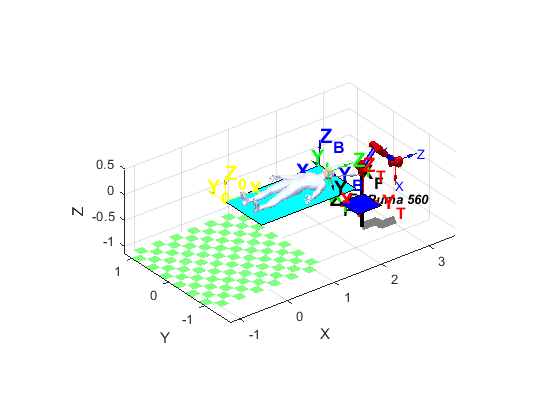

mdl_puma560
base = tableTransform * transl(2.5, -0.5, 0);
p560.base = base;

% Imaginary tool, with length 0.1m
p560.tool = transl(0,0,0.1); 
offset = Transform([0.1, 0, 0],rotation);

p560.plot(qn, 'base');
axis equal
axis tight


% End Efector
E = p560.fkine(qn);
% trplot(E, ... 
%        'frame', 'E', ... >
%        'color', 'k',...
%        'arrow',...
%        'length', length,...	
%        'text_opts', {'FontSize', 15, 'FontWeight', 'bold'},...
%        'width', width);
    
% Robot Base
R = p560.base;
% trplot(R, ... 
%        'frame', 'R', ... 
%        'color', 'm',...
%        'arrow',...
%        'length', length,...	
%        'text_opts', {'FontSize', 15, 'FontWeight', 'bold'},...
%        'width', width);

7.- Get the transformation that maps tumor points in Robot Frame.

*Add your comemnts here.....be concise*

T_T_R = inv(E.T);

8.- Print the tumor points in Robot Frame.

*Add your comemnts here.....be concise*

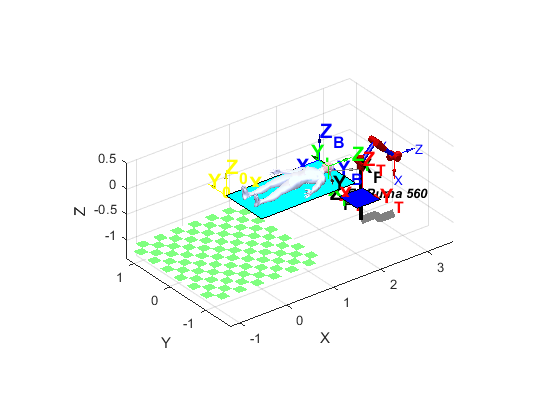

p = Transform(tumor.Vertices, T_T_R);
scatter3(p(:,1),p(:,2),p(:,3),2);
axis equal
axis tight

9.- Prepare a script that perform a biopsy. Zoom in the scene

*The robot (end effector) takes a small sample from the tumor. Upon entering the pacients skull, the robot moves slowly following a straight line in the longitudinal axis of the patient until it reaches the center of the tumor.*

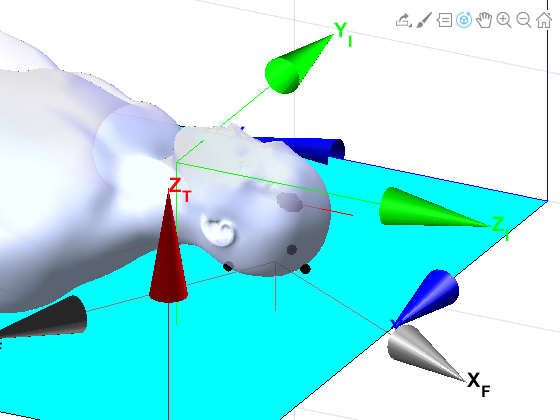

% Delete the skull from the plot for better view of the tumor
delete(SkullPatch) 

set(gca, 'CameraTarget', mean(tumor.Vertices));
if applyTransform
    set(gca, 'CameraPosition', mean(tumor.Vertices)+Transform([1 -2 1],rotation));
else
    set(gca, 'CameraPosition', mean(tumor.Vertices)+[1 -2 1]);
end
t = [0:0.05:4]';
tslow = [0:0.05:8]';

% Move to the pacients skull (Top in longitudinal axis)
T0 = E.T;
skullTop = mean(tumor.Vertices) + Transform([0.1,0,0], rotation);
TCrane = transl(skullTop + offset)*rotation*troty(-pi/2);
QEC = p560.jtraj(T0, TCrane, t);


% From skull to the tumor, slowly and in a straight line
TTumor = transl(mean(tumor.Vertices)+offset)*rotation*troty(-pi/2);
QCT = p560.jtraj(TCrane, TTumor, tslow);


v1=skullTop;
v2=mean(tumor.Vertices);
v=[v2;v1];
plot3(v(:,1),v(:,2),v(:,3),'r')

Q = [QEC;QCT];
Q = [Q;flipud(Q)];
p560.plot(Q, 'zoom', 1.5);

10.- Prepare a script that perform trepanation.

*The robot moves to the point of the skull with 45 deg with respect the  longitudinal axis of the human body. And makes a circular trajectory (a hole with the size of the tumor). *

*The circle is made with a the function circle3d giving it as parameter the center (the point in the skull with 45 deg from the tumor w.r.t. the longitudinal axis), the normal vector of this surface, and a radius (same as the tumor's). *

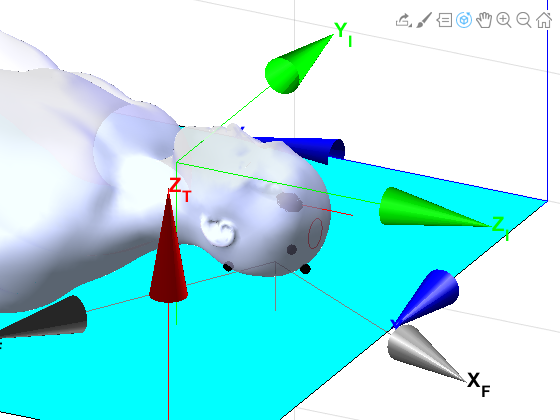

% Find the radius of the tumor
[n, ~] = size(tumor.Vertices);
m = mean(tumor.Vertices);
rad = 0;
for i=1:n
    r = pdist([m;tumor.Vertices(i,:)],'euclidean');
    rad = max(rad,r);
end

% A point in the skull with 45 degree to the longitudinal axis of the human
offsetTrep = 0.04;

center = m + Transform([offsetTrep,0,-offsetTrep], rotation);

normal = [1,0,0];
points = circle3D(center, Transform(normal, rotation), rad);
plot3(points(:,1),points(:,2),points(:,3),'r-');

t = [0:0.05:4]';

[n,v] = size(points);

% Reduce the n points given by circle3D to circlePoints
circlePoints = 50; % Wanted circle points
steps = round(n/circlePoints);
firstPoint = points(steps,:);
FirstT = transl(firstPoint+[0.1,0,-0.1])*troty(-pi/4);
Q = p560.jtraj(E.T, FirstT, t); % Trajectory from end effector to the first point

timeForTrep = 3; % Time(s) to complete the whole trepanation's circle 
tTrep = [0, timeForTrep/circlePoints]'; % n points, each point timeForTrep seconds.

% Trajectory to complete the circle
for i = [steps*2:steps:n]
    T1 = transl(points(i-1,:)+[0.1,0,-0.1])*troty(-pi/4);
    T2 = transl(points(i,:)+[0.1,0,-0.1])*troty(-pi/4);
    Qi = p560.jtraj(T1, T2, tTrep);
    Q = [Q;Qi];
end

% T2 = last point of the circle of the trajectory
Q2 = p560.jtraj(T2, E.T, t);
Q = [Q; Q2];
p560.plot(Q, 'zoom', 1.5);

11.- Prepare a script that perform tumor burning with the laser.

*For this exercise,we place the tool in the line created by the center of the tumor and the centre of the circle and start swinging the robotic arm relative to the centre of the circle in order to reach the tumor points (which have been greatly reduced to accelerate execution time since the tool already burns a big area) until all the tumor points are burnt. Finally we remove the tool and get the robot back to its original position. *

T0 = E.T;

% vector from tumor's center to hole's center
vector = m - center;
vector = vector / norm(vector);
vector = vector * 0.4;

% find angvec of this vector
rot = vrrotvec([0,0,1],vector);
rot = angvec2tr(rot(4), rot(1:3));

T1 = transl(m - vector) * rot;

% plot this vector
v1 = m - vector;
v2 = m;
v=[v2;v1];
plot3(v(:,1),v(:,2),v(:,3),'b')

t = [0:0.05:5]';
Q1 = p560.jtraj(T0, T1, t); % Trajectory from end effector to place the tool on the skull

Q = Q1;
% Enter to the skull, and touch the first tumors center
for i = 0.39:-0.01:0.2
    vector = m - center;
    vector = vector / norm(vector);
    vector = vector * i;
    T2 = transl(m - vector) * rot;
    t = [0:0.05:0.1]';
    Q2 = p560.jtraj(T1, T2, t); % Trajectory from skull to place the tool on the tumor
    T1 = T2;
    Q = [Q; Q2];
end
p560.plot(Q, 'zoom', 1.5);

scaleSphere = 0.004; % 4mm of radius for the spheres

[n, ~] = size(tumor.Vertices)

n = 13583

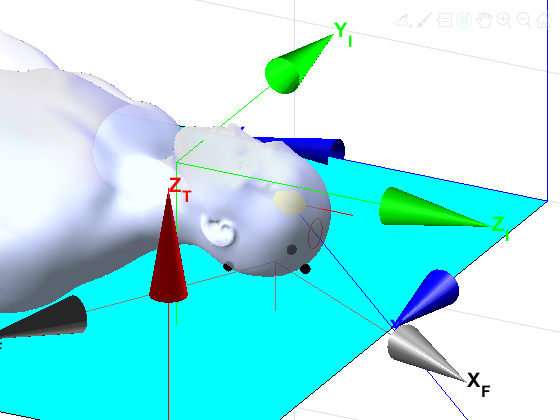

% Burn the whole tumor by going through all its points
for i = 1:50:n
    % Yellow spheres to represent burnt area
    [X, Y, Z] = sphere;
    X = X*scaleSphere+tumor.Vertices(i,1); Y = Y*scaleSphere+tumor.Vertices(i,2); 
    Z = Z*scaleSphere+tumor.Vertices(i,3);
    surf(X,Y,Z, 'FaceColor', 'yellow', 'EdgeColor','yellow');
    
    vector = tumor.Vertices(i,:) - center;
    vector = vector / norm(vector);
    vector = vector * 0.2;
    rot = vrrotvec([0,0,1],vector);
    rot = angvec2tr(rot(4), rot(1:3));
    T2 = transl(tumor.Vertices(i,:) - vector) * rot;
    t = [0:0.01:0.01]';
    Q = p560.jtraj(T1, T2, t);
    T1 = T2;
    p560.plot(Q , 'zoom', 1.5);
end

% From the last point to the center of the tumor
vector = m - center;
vector = vector / norm(vector);
vector = vector * 0.2;
rot = vrrotvec([0,0,1],vector);
rot = angvec2tr(rot(4), rot(1:3));
T2 = transl(m - vector) * rot;

Q = p560.jtraj(T1, T2, t);
p560.plot(Q, 'zoom', 1.5);
T1 = T2;

% Exit the skull of the pacient
for i = 0.21:0.01:0.4
    vector = m - center;
    vector = vector / norm(vector);
    vector = vector * i;
    T2 = transl(m - vector) * rot;
    t = [0:0.05:0.1]';
    Q = p560.jtraj(T1, T2, t); 
    T1 = T2;
    p560.plot(Q, 'zoom', 1.5);
end

t = [0:0.05:5]';
Q = p560.jtraj(T2, T0, t);
p560.plot(Q, 'zoom', 1.5);

12.-Modify your code  to repeat point from 7 till 11 if ZX plane of the Robot is not aligned with the plane of symmetry of the human body. There is a free rotation among these two planes. 

*See: * *‘Sckeching_Key_ideas_students.mlx’ and ‘Triangles_2.mlx’ for inspiration.*

*In our case is simply switching the tableTransform to true, to make all these changes*

%% put your code Here


## Functions

function vertex = Transform(vertex, transformation)
    % Function to apply transformations to a matrix where each row is a 3 coordinate point. 
    % Example: 
    % vertex = [0 0 0;
    %           1 1 1]
    % transform = transl(1, 0, 0)
    % result: vertex = [1 0 0;
    %                   2 1 1];
    vertex = [vertex'; ones(1, size(vertex,1))];
    vertex = transformation*vertex;
    vertex = vertex(1:3,:);
    vertex = vertex';
end


% Taken from: https://www.mathworks.com/matlabcentral/fileexchange/26588-plot-circle-in-3d
% and modified for our need

% Create a circle giving the center, a normal vector and a radius.
function [points] = circle3D(center,normal,radius) 
    theta = 0:0.01:2*pi;
    v = null(normal);
    points = repmat(center',1,size(theta,2))+radius*(v(:,1)*cos(theta)+v(:,2)*sin(theta));
    points = points';
end